dataset = 'exdata1.mat';
load(dataset);
% Combine data into one matrix so that assigned labels are kept with features during random selection
Data = [X, y]; 
% Reserve 20% of data for testing 
cv = cvpartition(size(Data,1),'HoldOut',0.2);
% Training data
X = Data(cv.training,1:2); 
y = Data(cv.training,3);
% Test data
X_test = Data(cv.test,1:2)

X_test =     2.7822    4.0431
    3.1048    3.0709
    1.9182    4.0534
    3.1855    4.2888
    3.0473    2.2931
    1.8721    2.0577
    1.8951    2.9174
    1.6878    2.4057
    1.4919    2.0271
    2.0910    1.6177


y_test = Data(cv.test,3)

y_test =      1
     1
     1
     1
     0
     0
     0
     0
     0
     0


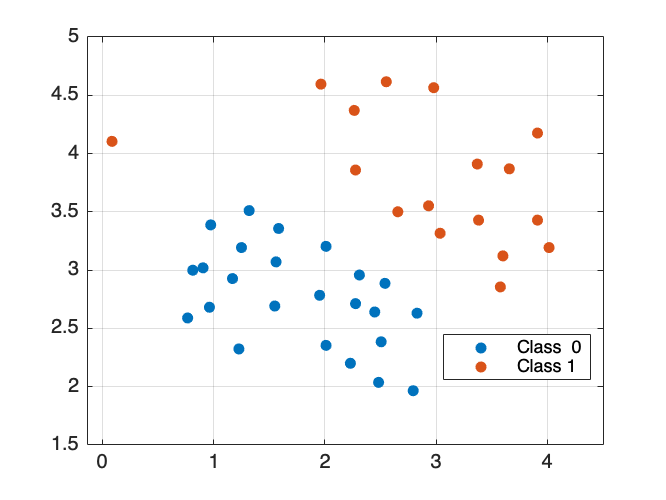


Feature_map = true;
if Feature_map
    X = Feature_mapping(X(:,1), X(:,2));
    X_test = Feature_mapping(X_test(:,1), X_test(:,2));
end

% Resize X by adding the bias term theta0
X = [ones(size(X,1),1),X];
X_test = [ones(size(X_test,1),1),X_test];

figure
hold on
gscatter(X(:,2),X(:,3),y) 
legend('Class  0', 'Class 1')
box on
grid on


% Model and Training

theta_init = zeros(size(X, 2), 1);
lambda = 100;
% Set Options
options = optimoptions(@fminunc);
options.Algorithm = 'Quasi-Newton';
options.GradObj =  'on';
options.MaxIter =  1000;
% Optimize
[theta, J, exit_flag] = fminunc(@(th)(CostFun_and_Grad(th, X, y, lambda)), theta_init, options);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>



% Begin by setting all the predictions to label 0
label = zeros(size(X_test,1),1);
% Classify predictions above a specific threshold with label 1:
threshold = 0.5;
label(sigmoid(X_test*theta) >= threshold) = 1;

% Metrics for classification
TP = sum(and(label,y_test));                % True positives
FP = sum(and(label,not(y_test)));           % False positives
TN = sum(and(not(label),not(y_test)));      % True negatives
FN = sum(and(not(label),y_test));           % False negatives

accuracy  = (TP + TN)/(TP + TN + FP + FN)

accuracy = 1

precision = TP/(TP + FP)

precision = 1

recall    = TP/(TP + FN)

recall = 1

F1score   = (2*precision*recall)/(precision + recall)

F1score = 1

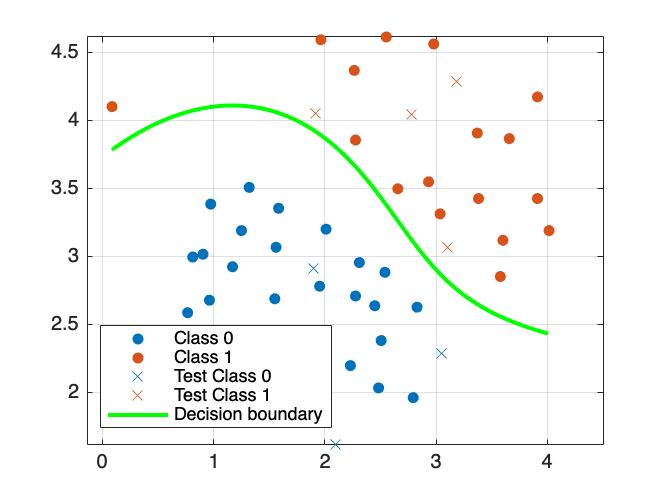


% Compute the scores over a grid
d = 0.02; % Step size of the grid
x1 = min(X(:,2)):d:max(X(:,2));
x2 = min(X(:,3)):d:max(X(:,3));
[x1Grid, x2Grid] = meshgrid(x1,x2);
% The grid
if Feature_map
    X_Grid = Feature_mapping(x1Grid(:), x2Grid(:));
else
    X_Grid = [x1Grid(:),x2Grid(:)];        
end
X_Grid = [ones(numel(x1Grid),1),X_Grid];
scores = sigmoid(X_Grid*theta); % The scores

figure
hold on
% Plots data
gscatter(X(:,2),X(:,3),y) 
gscatter(X_test(:,2),X_test(:,3),label,[],'x') 
% Plot decision boundary:
contour(x1Grid,x2Grid,reshape(scores,size(x1Grid)),[threshold threshold],'g', 'LineWidth',2);
legend('Class 0','Class 1','Test Class 0','Test Class 1','Decision boundary')
box on 
grid on
hold off


dataset = 'exdata2.mat';
load(dataset);
% Combine data into one matrix so that assigned labels are kept with features during random selection
Data = [X, y]; 
% Reserve 20% of data for testing 
cv = cvpartition(size(Data,1),'HoldOut',0.2);
% Training data
X = Data(cv.training,1:2); 
y = Data(cv.training,3);
% Test data
X_test = Data(cv.test,1:2)

X_test =     0.1071    0.6031
    0.2108    0.8662
    0.7730    0.8545
    0.7500    0.7917
    0.8145    0.8852
    0.4942    0.8999
    0.4804    0.8633
    0.4988    0.9452
    0.0749    0.8721
    0.0588    0.8721


y_test = Data(cv.test,3)

y_test =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


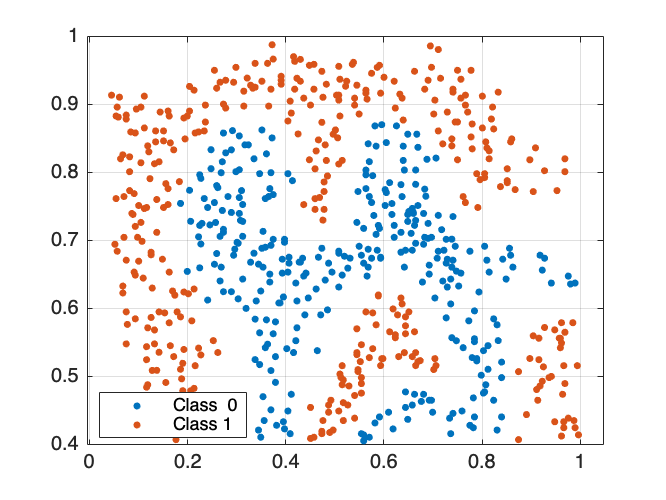


figure
hold on
gscatter(X(:,1),X(:,2),y) 
legend('Class  0', 'Class 1')
box on
grid on


SVMModel = fitcsvm(X,y,...
    'KernelFunction','polynomial',...
    'PolynomialOrder',8,... % add only when polynomial kernel selected
    'Standardize',true, ...
    'BoxConstraint',1,...
    'Verbose', 0);

% Return labels and probabilities of prediction
[label,~] = predict(SVMModel,X_test); 
% Metrics for classification
TP = sum(and(label,y_test));                % True positives
FP = sum(and(label,not(y_test)));           % False positives
TN = sum(and(not(label),not(y_test)));      % True negatives
FN = sum(and(not(label),y_test));           % False negatives

accuracy  = (TP + TN)/(TP + TN + FP + FN)

accuracy = 0.9826

precision = TP/(TP + FP)

precision = 0.9900

recall    = TP/(TP + FN)

recall = 0.9802

F1score   = (2*precision*recall)/(precision + recall)

F1score = 0.9851

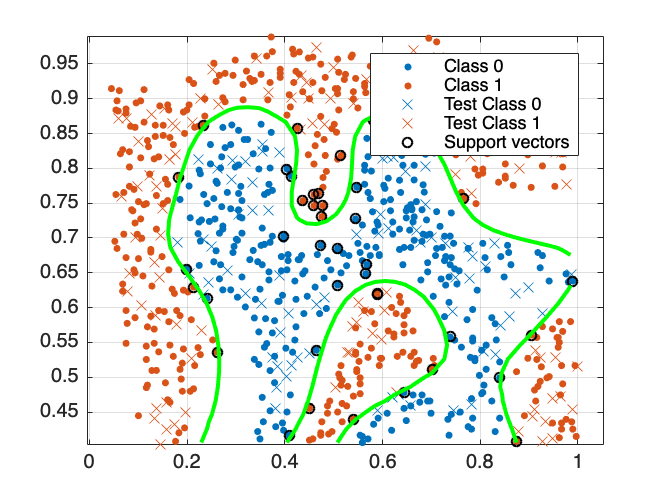


% Compute the scores over a grid
d = 0.02; % Step size of the grid
x1 = min(X(:,1)):d:max(X(:,1));
x2 = min(X(:,2)):d:max(X(:,2));
[x1Grid, x2Grid] = meshgrid(x1,x2);
xGrid = [x1Grid(:),x2Grid(:)];        % The grid
[~,scores] = predict(SVMModel,xGrid); % The scores

% Plot model with data and support vectors
sv = SVMModel.SupportVectors;
figure
hold on
% Plots data
gscatter(X(:,1),X(:,2),y) 
gscatter(X_test(:,1),X_test(:,2),label,[],'x') 
% Plot Support Vectors
plot(X(SVMModel.IsSupportVector,1),X(SVMModel.IsSupportVector,2),'ko','MarkerSize',5,'LineWidth',1);
% Plot decision boundary
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'g', 'LineWidth',2);
legend('Class 0','Class 1','Test Class 0','Test Class 1','Support vectors')
hold off
box on
grid on